clear all
% Kinematic variables
syms x phi theta
X = [x,theta,phi]

$$X = \left(\begin{array}{ccc} x & \theta & \varphi \end{array}\right)$$

% % RBs constants
% syms m1 J1 L1 m2 J2 h m3 J3 L3 g
% % Spring and dampers constants
% syms k1 c1 k2 c2 k3 c3
% % External forces
% syms F01 F02
% % Initial conditions
% syms L0 theta0 phi0
% syms delta0_l1 delta0_l2 delta0_l3

% VALUES
g=9.81;
m1=10;
m2=5;
m3=10;
J1=0.2;
J2=0.1;
J3=0.2;
L1=0.5;
L3=0.5;
h= 0.1;
k1=3e3;
k2=6e3;
k3=3e3;
c1=3;
c2=3;
c3=3;
F01 = 1;
F02 = 1;
L0 = 0.75;
theta0 = pi/6;
phi0 = pi/6;
delta0_l1 = -0.055;
delta0_l2 = -0.016;
delta0_l3 = 0.009;

X0 = [L0,theta0,phi0]

X0 =     0.7500    0.5236    0.5236



% Kinematic relationships
xg1 = L1*cos(theta)

$$xg1 = \frac{\cos\left(\theta \right)}{2}$$

yg1 = L1*sin(theta)

$$yg1 = \frac{\sin\left(\theta \right)}{2}$$

xg2 = x*cos(theta) - h*sin(theta)

$$xg2 = x\,\cos\left(\theta \right)-\frac{\sin\left(\theta \right)}{10}$$

yg2 = x*sin(theta) - h*cos(theta)

$$yg2 = x\,\sin\left(\theta \right)-\frac{\cos\left(\theta \right)}{10}$$

xg3 = xg2 + L3*sin(phi)

$$xg3 = \frac{\sin\left(\varphi \right)}{2}-\frac{\sin\left(\theta \right)}{10}+x\,\cos\left(\theta \right)$$

yg3 = yg2 - L3*cos(phi)

$$yg3 = x\,\sin\left(\theta \right)-\frac{\cos\left(\theta \right)}{10}-\frac{\cos\left(\varphi \right)}{2}$$

xe = xg2 + 2*L3*sin(phi)

$$xe = \sin\left(\varphi \right)-\frac{\sin\left(\theta \right)}{10}+x\,\cos\left(\theta \right)$$

yb = 2*L1*sin(theta)

$$yb = \sin\left(\theta \right)$$


delta0_l = diag([delta0_l1 delta0_l2 delta0_l3]);

delta_l1 = yb

$$delta\_l1 = \sin\left(\theta \right)$$

delta_l2 = x

$$delta\_l2 = x$$

delta_l3 = xe

$$delta\_l3 = \sin\left(\varphi \right)-\frac{\sin\left(\theta \right)}{10}+x\,\cos\left(\theta \right)$$


hg1 = yg1;
hg2 = yg2;
hg3 = yg3;
Hg = [hg1, hg2, hg3]

$$Hg = \left(\begin{array}{ccc} \frac{\sin\left(\theta \right)}{2} & x\,\sin\left(\theta \right)-\frac{\cos\left(\theta \right)}{10} & x\,\sin\left(\theta \right)-\frac{\cos\left(\theta \right)}{10}-\frac{\cos\left(\varphi \right)}{2} \end{array}\right)$$


% Kinetic energy
Mph = diag([m1,m1,J1,m2,m2,J2,m3,m3,J3]);
Ym = [xg1,yg1,theta,xg2,yg2,theta,xg3,yg3,phi];
Lm = jacobian(Ym,X);
Lm0 = subs(Lm,X,X0)

$$Lm0 = \begin{array}{l} \left(\begin{array}{ccc} 0 & -\frac{1}{4} & 0\\ 0 & \frac{\sqrt{3}}{4} & 0\\ 0 & 1 & 0\\ \frac{\sqrt{3}}{2} & -\frac{\sqrt{3}}{20}-\frac{3}{8} & 0\\ \frac{1}{2} & \sigma_{1} & 0\\ 0 & 1 & 0\\ \frac{\sqrt{3}}{2} & -\frac{\sqrt{3}}{20}-\frac{3}{8} & \frac{\sqrt{3}}{4}\\ \frac{1}{2} & \sigma_{1} & \frac{1}{4}\\ 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,\sqrt{3}}{8}+\frac{1}{20} \end{array}$$

M = Lm0'*Mph*Lm0;


% Disipation equations
Cph = diag([c1 c2 c3]);
Yc = [delta_l1, delta_l2 delta_l3];
Lc = jacobian(Yc,X);
Lc0 = subs(Lc,X,X0)

$$Lc0 = \left(\begin{array}{ccc} 0 & \frac{\sqrt{3}}{2} & 0\\ 1 & 0 & 0\\ \frac{\sqrt{3}}{2} & -\frac{\sqrt{3}}{20}-\frac{3}{8} & \frac{\sqrt{3}}{2} \end{array}\right)$$

C = Lc0'*Cph*Lc0;


% Potential energy
% Stiffness energy
Kph = diag([k1 k2 k3]);
Yk = [delta_l1, delta_l2, delta_l3];
Lk = jacobian(Yk,X);
Lk0 = subs(Lk,X,X0)

$$Lk0 = \left(\begin{array}{ccc} 0 & \frac{\sqrt{3}}{2} & 0\\ 1 & 0 & 0\\ \frac{\sqrt{3}}{2} & -\frac{\sqrt{3}}{20}-\frac{3}{8} & \frac{\sqrt{3}}{2} \end{array}\right)$$

K = Lk0'*Kph*Lk0;

% Second stiffness moment
KII_total0 = 0;
index = find(Kph);
counter=1;
for delta_l = Yk
    KII_delta_l  = hessian(delta_l,X);
    KII_delta_l0 = subs(KII_delta_l,X,X0)
    idx = index(counter);
    current_stiff_moment = Kph(idx)*delta0_l(idx)
    counter = counter + 1;
    KII_total0 = KII_total0 + KII_delta_l0*current_stiff_moment;
end

$$KII\_delta\_l0 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & -\frac{1}{2} & 0\\ 0 & 0 & 0 \end{array}\right)$$

current_stiff_moment = -165

$$KII\_delta\_l0 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

current_stiff_moment = -96

$$KII\_delta\_l0 = \left(\begin{array}{ccc} 0 & -\frac{1}{2} & 0\\ -\frac{1}{2} & \frac{1}{20}-\frac{3\,\sqrt{3}}{8} & 0\\ 0 & 0 & -\frac{1}{2} \end{array}\right)$$

current_stiff_moment = 27.0000

KII_total0

$$KII\_total0 = \left(\begin{array}{ccc} 0 & -\frac{27}{2} & 0\\ -\frac{27}{2} & \frac{1677}{20}-\frac{81\,\sqrt{3}}{8} & 0\\ 0 & 0 & -\frac{27}{2} \end{array}\right)$$


% Gravitational energy
Vgph = diag([m1 m2 m3]);
Kg_total0 = 0;
index = find(Vgph);
counter=1;
for hg = Hg
    Kg_h  = hessian(hg,X);
    Kg_h0 = subs(Kg_h,X,X0)
    current_weigth = Vgph(index(counter))*g
    counter = counter + 1;
    Kg_total0 = Kg_total0 + Kg_h0*current_weigth;
end

$$Kg\_h0 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & -\frac{1}{4} & 0\\ 0 & 0 & 0 \end{array}\right)$$

current_weigth = 98.1000

$$Kg\_h0 = \left(\begin{array}{ccc} 0 & \frac{\sqrt{3}}{2} & 0\\ \frac{\sqrt{3}}{2} & \frac{\sqrt{3}}{20}-\frac{3}{8} & 0\\ 0 & 0 & 0 \end{array}\right)$$

current_weigth = 49.0500

$$Kg\_h0 = \left(\begin{array}{ccc} 0 & \frac{\sqrt{3}}{2} & 0\\ \frac{\sqrt{3}}{2} & \frac{\sqrt{3}}{20}-\frac{3}{8} & 0\\ 0 & 0 & \frac{\sqrt{3}}{4} \end{array}\right)$$

current_weigth = 98.1000

Kg_total0

$$Kg\_total0 = \left(\begin{array}{ccc} 0 & \frac{2943\,\sqrt{3}}{40} & 0\\ \frac{2943\,\sqrt{3}}{40} & \frac{2943\,\sqrt{3}}{400}-\frac{12753}{160} & 0\\ 0 & 0 & \frac{981\,\sqrt{3}}{40} \end{array}\right)$$


% Total potential energy
K = Lk0'*Kph*Lk0 + KII_total0 + Kg_total0;

% Virtual work
Yq = [yb, xe];
Lq = jacobian(Yq,X);
Lq0 = subs(Lq,X,X0)

$$Lq0 = \left(\begin{array}{ccc} 0 & \frac{\sqrt{3}}{2} & 0\\ \frac{\sqrt{3}}{2} & -\frac{\sqrt{3}}{20}-\frac{3}{8} & \frac{\sqrt{3}}{2} \end{array}\right)$$

F = [F01;F02];
Q = Lq0'*F;


%% Frequency response
M = double(M)

M =    15.0000   -0.7500    5.0000
   -0.7500   13.3361   -0.2500
    5.0000   -0.2500    2.7000


C = double(C)

C =     5.2500   -1.1993    2.2500
   -1.1993    2.8892   -1.1993
    2.2500   -1.1993    2.2500


K = double(K)

K = 	1.0e+03 *

    8.2500   -1.0853    2.2500
   -1.0853    2.8886   -1.1993
    2.2500   -1.1993    2.2790


Q = double(Q)

Q =     0.8660
    0.4044
    0.8660


[modes eigenvalues]=eig(M\K);
modes

modes =     0.3410   -0.9303   -0.0104
    0.0403    0.2125   -0.8500
   -0.9392   -0.2988   -0.5266


freq=sqrt(diag(eigenvalues))/(2*pi)

freq =     6.5430
    3.7311
    2.0250


yg2;

$$yg2 = x\,\sin\left(\theta \right)-\frac{\cos\left(\theta \right)}{10}$$

dyg2dx = diff(yg2,x);

$$dyg2dx = \sin\left(\theta \right)$$

dyg2dx0 = subs(dyg2dx,X,X0);

$$dyg2dx0 = \frac{1}{2}$$

dyg2dtheta = diff(yg2,theta);

$$dyg2dtheta = \frac{\sin\left(\theta \right)}{10}+x\,\cos\left(\theta \right)$$

dyg2dtheta0 = subs(dyg2dtheta,X,X0);

$$dyg2dtheta0 = \frac{3\,\sqrt{3}}{8}+\frac{1}{20}$$

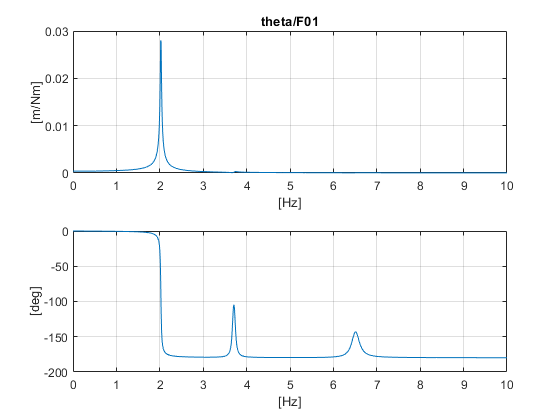


F01 = 1;
F02 = 0;
F = [F01;F02];
Q = Lq0'*F;

vect_f=0:0.01:10;
omega=vect_f.*(2*pi);
for k = 1 : length(omega)
    om=omega(k);
    A = -om^2*M+i*om*C+K;
    x0_num = double(A\Q);
    x_num = double(x0_num(1));
    theta_num = double(x0_num(2));
    phi_num = double(x0_num(3));
    
    mod_x(k)=double(abs(x_num));
    phase_x(k)=double(angle(x_num));
   
    yg2_num = dyg2dx0*x_num + dyg2dtheta0*theta_num;
    mod_yg2(k)=double(abs(yg2_num));
    phase_yg2(k)=double(angle(yg2_num));
    
    mod_theta(k)=double(abs(theta_num));
    phase_theta(k)=double(angle(theta_num));
    
    mod_phi(k)=double(abs(phi_num));
    phase_phi(k)=double(angle(phi_num));
end

figure
subplot 211;plot(vect_f,mod_theta);grid;xlabel('[Hz]');ylabel('[m/Nm]');title('theta/F01')
subplot 212;plot(vect_f,phase_theta*180/pi);grid;xlabel('[Hz]');ylabel('[deg]')

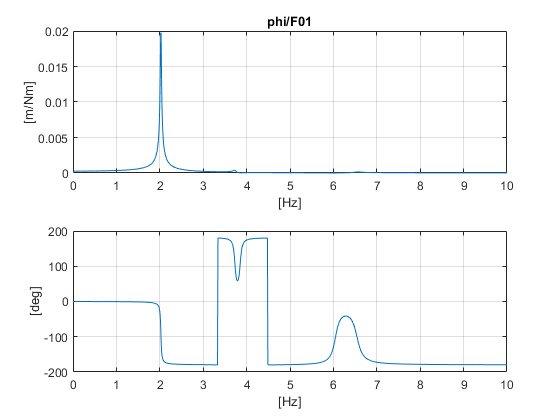

figure
subplot 211;plot(vect_f,mod_yg2);grid;xlabel('[Hz]');ylabel('[m/Nm]');title('yd/F01')
subplot 212;plot(vect_f,phase_yg2*180/pi);grid;xlabel('[Hz]');ylabel('[deg]')